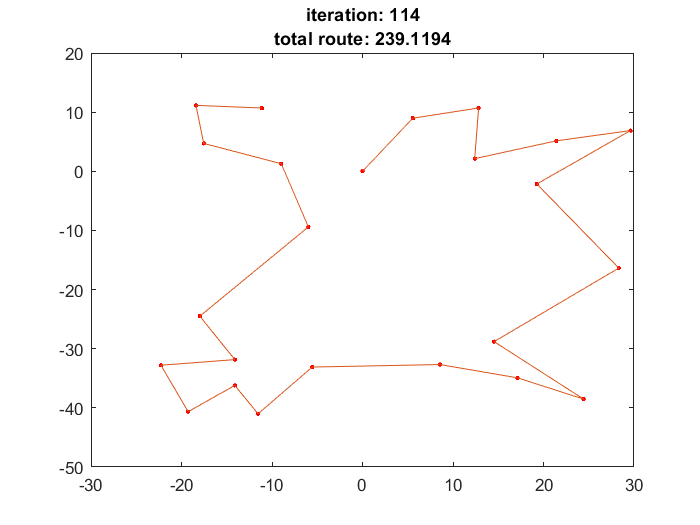

sortedCoords =   -11.1142   10.6972
  -18.4031   11.1456
  -17.5441    4.7116
   -8.9747    1.2824
   -5.9816   -9.4053
  -17.9736  -24.4954
  -14.1124  -31.8407
  -22.2743  -32.7920
  -19.2625  -40.6440
  -14.1124  -36.2021


sortedCoords_ID =      9
    18
    11
    15
     2
    21
     7
    19
    12
    23


NASA_pos_xy = [...
    0, 0;...
    10, -11;...
    15, -9;...
    19, -14;...
    13, -16;...
    14, -20;...
    11, -24;...
    8, -29;...
    6, -36;...
    3, -33;...
    -1, -38;...
    -6, -35;...
    -6, -33;...
    -9, -30;...
    -13, -27;...
    -14, -22;...
    -18, -18;...
    -19, -10;...
    -22, -5;...
    -16, -4;...
    -15, 0
    -11, 4;...
    -7, 9;...
    -10, 12;...
    -4, 12;...
    -2, 14;...
    1, 16;...
    5, 13;...
    7, 9;...
    11, 3;...
    14, -6;...
    16, -1];


  
David_pos_xy = [...
 0	0;...
8.08643625170519	-8.90346297042091;...
12.0962049877865	-7.27275793324958;...
15.2765647016225	-11.2929031869501;...
10.4411157230304	-12.8700829245614;...
11.2408978900490	-16.0869158735612;...
8.81104004438252	-19.2446229154034;...
6.39077706258389	-23.1796884054583;...
4.76681071979470	-28.6103536929290;...
2.37950693613863	-26.1758512671689;...
-0.792479017663119	-30.1127930374792;...
-4.74766703214238	-27.7041373255866;...
-4.76082438287698	-26.1935735909423;...
-7.15844509787753	-23.8787287484616;...
-10.3600893864853	-21.5494375203446;...
-11.1858174517787	-17.6087468385248;...
-14.4136933812165	-14.4552974226872;...
-15.2435459717407	-8.04879972840984;...
-17.6718854930525	-4.03394559801030;...
-12.8737205654014	-3.22552090826114;...
-12.0995160990644	-1.91228902862730e-19;...
-8.88342333460234	3.23386579430746;...
-5.65797487303648	7.27782057522501;...
-8.07511948403878	9.69925347805461;...
-3.22916754858482	9.68915399105145;...
-1.61519926875386	11.3071273899207;...
0.806910159530438	12.9110634010906;...
4.03468795612636	10.4927528517213;...
5.65534213559957	7.27399702956192;...
8.89193109496106	2.42752076335689;...
11.3067398907337	-4.85455517811034;...
12.9071795629853	-0.808530846186197];

% There's usually an extra 4.5 mm added
dist2plane = 80; % Changed from 75

[Nref, target_cen, p2, p_xray, h_xray, pivot_point] = PIXLmodel(dist2plane);
%rot_apriori = [0, 0, 0];

%hexa_file_name = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\GenerateScanPattern\2022_12_21_10_40_31_70mm\2022_12_21_10_26_10.txt';
%hexa_file_name = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\GenerateScanPattern\2022_12_21_11_23_57_70mmWade\2022_12_21_11_12_18.txt';
% % hexa_file_name = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\GenerateScanPattern\2022_12_21_11_23_57_70mmWade\2022_12_21_11_12_18.txt';
% % 
% % file = fileread(hexa_file_name);
% % 
% % [hexa_string_all, hexa_string] = deal([]);
% % 
% % hexa_string_all(1,:) = strfind(file,"X: ");
% % hexa_string_all(2,:) = strfind(file,", Y");
% % hexa_string_all(3,:) = strfind(file,"Y: ");
% % hexa_string_all(4,:) = strfind(file,", Z");
% % hexa_string_all(5,:) = strfind(file,"Z: ");
% % hexa_string_all(6,:) = strfind(file,", U");
% % hexa_string_all(7,:) = strfind(file,"U: ");
% % hexa_string_all(8,:) = strfind(file,", V");
% % hexa_string_all(9,:) = strfind(file,"V: ");
% % hexa_string_all(10,:) = strfind(file,", W");
% % hexa_string_all(11,:) = strfind(file,"W: ");
% % for i=1:size(hexa_string_all,1)
% %     hexa_string(i,:) = hexa_string_all(i,2:2:end);
% % end
% % hexa_string(12,:) = strfind(file,", T");
% %  
% % for j=1:size(hexa_string,2)
% %     for i=1:size(hexa_string,1)/2
% %         hexa_pos(i,j) = double(string(file(hexa_string(i*2-1,j)+3:hexa_string(i*2,j)-1)));
% %     end
% % end
% % hexa_pos(1,:) = hexa_pos(1,:);
% % hexa_pos(2,:) = hexa_pos(2,:);
% % hexa_pos(3,:) = hexa_pos(3,:);
% % hexa_pos(4,:) = hexa_pos(4,:);
% % hexa_pos(5,:) = hexa_pos(5,:);
% %  
% % %sli_file_path = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\GenerateScanPattern\2022_12_21_10_40_31_70mm\download\';
% % %sli_file_path = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\GenerateScanPattern\2022_12_21_11_23_57_70mmWade\download\';
% % sli_file_path = 'C:\Users\jonas\OneDrive - Danmarks Tekniske Universitet\Skrivebord\Tidligere kurser & bøger\30220 Synthesis in Earth and Space Physics Fall 22\Repo\GenerateScanPattern\2022_12_21_11_23_57_70mmWade\download\';
% % 
% % [sparseQ, sparseN, sparseD] = deal([]);
% % sli_files = dir([sli_file_path '*.unk']);
% % for i=1:length(sli_files)
% %     [h,sli(i,:),m] = readAscImage([sli_file_path sli_files(i).name]);  
% %     
% %     sparse = [sli(i,:).sliData.Q(sli(i,:).sliData.sliID ~= 255, :)/1e3, sli(i,:).sliData.sliID(sli(i,:).sliData.sliID ~= 255, :)];
% %     N_s = sli(i,:).sliHeader.planeN;
% %     D_s = sli(i,:).sliHeader.planeD/1e3;
% %     
% %     sparseQ = [sparseQ; [sparse, i*ones(size(sparse, 1), 1)]];
% %     sparseN = [sparseN; [N_s, i*ones(size(N_s, 1), 1)]];
% %     sparseD = [sparseD; [D_s, i*ones(size(D_s, 1), 1)]];
% % end
% % hexa_pos(:,1:length(sli_files)) = hexa_pos(:,size(hexa_pos,2)-length(sli_files)+1:end) ;
% % %rot_apriori = [hexa_pos(4,:)',hexa_pos(5,:)',hexa_pos(6,:)'];
% % rot_apriori = rot_opt(sortedCoords_ID, :);
% % % Save the position of the X-ray on the survey area

rot_apriori_ = [
    0         0         0;...
    2.2000   -1.4000         0;...
    7.7000   -1.3000         0;...
    9.5000   -2.7000         0;...
   -2.5000    3.0000         0;...
   -1.2000    5.0000         0;...
    7.4000   -3.3000         0;...
    3.8000    6.6000         0;...
   -2.5000   -2.6000         0;...
    8.9000    5.7000         0;...
   -1.1000   -4.1000         0;...
    9.4000   -4.5000         0;...
    0.5000    4.5000         0;...
    6.7000    3.4000         0;...
   -0.3000   -2.1000         0;...
   -1.6000    6.9000         0;...
    7.6000    2.0000         0;...
   -2.6000   -4.3000         0;...
    7.6000   -5.2000         0;...
   -2.1000    1.3000         0;...
    5.7000   -4.2000         0;...
    8.1000    4.0000         0;...
    8.4000   -3.3000         0;...
   -0.5000    2.9000         0];

rot_24_2 = [...
0	0	0;...
2.2000	-1.4000	0;...
7.7000	-1.2000	0;...
9.6000	-2.4000	0;...
-2.5000	3.4000	0;...
-1.1000	5.4000	0;...
7.7000	-3.2000	0;...
4.2000	7	0;...
-2.7000	-2	0;...
9.1000	5.9000	0;...
-1	-3.6000	0;...
9.6000	-4.2000	0;...
0.5000	4.9000	0;...
7	3.7000	0;...
-4	-2.3000	0;...
-2.8000	-4.3000	0;...
-1.3000	7	0;...
7.9000	2.1000	0;...
7.5000	-4.7000	0;...
-1.4000	-5.6000	0;...
-2.3000	5.2000	0;...
0.7000	-3.3000	0;...
10	0.5000	0;...
8.9000	-5.9000	0];

dist2plane = 80;
    %[Nref, target_cen, p2, p_xray, h_xray, pivot_point] = PIXLmodel(dist2plane);
%h_xray = 25.5 + 1.60033/tan(18/180*pi);
    pos_xy = [];
for s = 1:size(rot_apriori_, 1)
    [R, Rc] = deal([]);
    R = createRotationMatrix(-rot_apriori(s, 3), -rot_apriori(s, 2), -rot_apriori(s, 1));
    R = [R, zeros(3, 1); ones(1, 4).*[0, 0, 0, 1]];
    
    % Rotation to align with base-frame
    best_angle_x = 18; % 18.27; % 18
    best_angle_y = 0; % -0.38; % 0
    best_angle_z = 0; % 0.2700; % 0
    Rc = createRotationMatrix(best_angle_z, best_angle_y, best_angle_x);
    Rc = [Rc, zeros(3, 1); ones(1, 4).*[0, 0, 0, 1]];
    
    T_p2 = [1, 0, 0, p2(1); 0, 1, 0, p2(2); 0, 0, 1, p2(3); 0, 0, 0, 1];
    T_base = [1, 0, 0, 0; 0, 1, 0, 0; 0, 0, 1, h_xray; 0, 0, 0, 1];
    pivot_point_r = (T_base^-1*T_p2*Rc*T_p2^-1*[pivot_point, 1]')'; 
    T_pivot = [1, 0, 0, pivot_point_r(1); 0, 1, 0, pivot_point_r(2); 0, 0, 1, pivot_point_r(3); 0, 0, 0, 1];
                    
    RT = T_pivot*R*T_pivot^-1*T_base^-1*T_p2*Rc*T_p2^-1;  
    target_cen_rot = T_base^-1*T_p2*Rc*T_p2^-1*[target_cen, 1]';
    target_cen_rot = target_cen_rot(1:3)';
    
    p_xray_rot = RT*[p_xray, 1]';
    p_xray_rot = p_xray_rot(1:3)';
    
    Nref_rot = R*Rc*[Nref, 1]';
    Nref_rot = Nref_rot(1:3)'; 
    
    % Find out where the rotated unit vectors intersect with the plane
    [pos_xy(s, :), ~] = line_plane_intersection(Nref_rot, p_xray_rot, [0, 0, 1], target_cen_rot); % target_cen_rot + [+0.5618, +0.4032, -40.7507]
end
%size(pos_xy)

pos = pos_xy;
clf
%prompt = "How many pictures would you like to use? ";
n_pictures = length(pos); %size(rot_opt, 1);
%n_pictures = input(prompt);

[sortedCoords, sortedCoords_ID, ~] = solveTSP([-pos(1:n_pictures, 1:2); [0, 0]], true);


sortedCoords = flip(sortedCoords(1:end-1, :))

sortedCoords =          0    0.0000
    5.5542    8.9770
   12.8270   10.7008
   12.3987    2.1387
   21.4132    5.1464
   29.6184    6.8865
   19.2625   -2.1425
   28.3189  -16.3650
   14.5410  -28.8026
   24.4296  -38.5178


sortedCoords_ID = flip(sortedCoords_ID(1:end-1, :))

sortedCoords_ID =      1
    20
     5
    24
     6
    16
    13
     8
    14
    10



T = array2table(round([(1:size(pos, 1))', sortedCoords], 3));

T.Properties.VariableNames(1:3) = {'N','posX','posY'};
writetable(T,'ScanPattern_24P.csv');


% NASA_pos_xy = [...
% 0,0;...
% -0.024,-2.242;...
% 4.691,-6.488;...
% 3.274,-14.046;...
% -4.748,-24.009;...
% 13.655,-17.378;...
% 24.552,-7.936;...
% 27.405,8.641;...
% 25.975,17.177;...
% 25.025,17.647;...
% 22.176,17.633;...
% 24.546,25.261;...
% 16.959,29.504;...
% 17.897,39.102;...
% 12.228,34.739;...
% 4.211,27.551;...
% -8.048,19.014;...
% -13.719,21.405;...
% -19.878,22.864;...
% -22.25,19.548;...
% -33.222,20.106;...
% -25.585,29.596;...
% -15.143,29.031;...
% -12.309,34.754;...
% -10.895,38.107;...
% -8.063,40.98];   


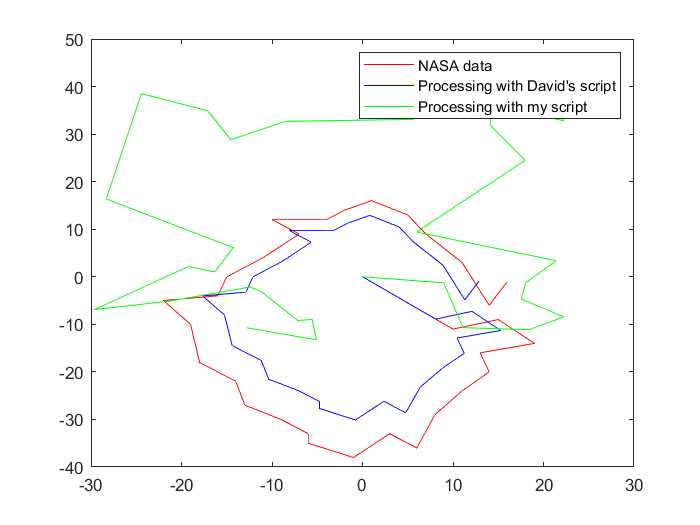



clf
figure(16)
plot(NASA_pos_xy(:, 1), NASA_pos_xy(:, 2), 'r-')
hold on
% David's appears to be scaled by a factor 25% - maybe it's because it's at
% different distances
%plot(David_pos_xy(:, 1).*1.25, David_pos_xy(:, 2).*1.25, 'b-')
plot(David_pos_xy(:, 1), David_pos_xy(:, 2), 'b-')

plot(pos_xy(sortedCoords_ID, 1), pos_xy(sortedCoords_ID, 2), 'g-')
%plot(-pos_xy(:, 1)*0.985, -pos_xy(:, 2)*0.985, 'g-')
%plot(-pos_xy(:, 1), -pos_xy(:, 2), 'g-')
%plot(pos_xy(:, 1).*0.9 - 2, pos_xy(:, 2).*0.9 -20, 'g-')
%plot(pos_xy(:, 1), pos_xy(:, 2), 'g-')

legend('NASA data', 'Processing with David''s script', 'Processing with my script')

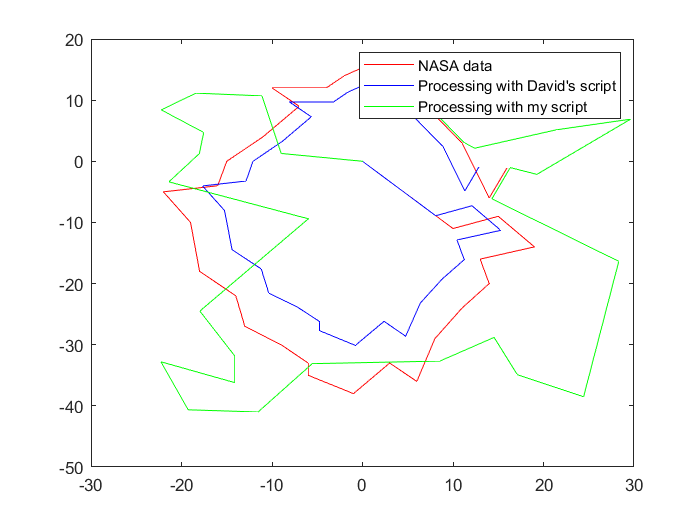


clf
figure(15)
plot(NASA_pos_xy(:, 1), NASA_pos_xy(:, 2), 'r-')
hold on
% David's appears to be scaled by a factor 25% - maybe it's because it's at
% different distances
% From 27 mm  to 75 mm s
%plot(David_pos_xy(:, 1).*1.25, David_pos_xy(:, 2).*1.25, 'b-') 
plot(David_pos_xy(:, 1), David_pos_xy(:, 2), 'b-')

%plot(pos_xy(:, 1), pos_xy(:, 2), 'g-')
%plot(-pos_xy(:, 1)*0.985, -pos_xy(:, 2)*0.985, 'g-')
plot(-pos_xy(sortedCoords_ID, 1), -pos_xy(sortedCoords_ID, 2), 'g-')
%plot(pos_xy(:, 1).*0.9 - 2, pos_xy(:, 2).*0.9 -20, 'g-')
%plot(pos_xy(:, 1), pos_xy(:, 2), 'g-')

legend('NASA data', 'Processing with David''s script', 'Processing with my script')

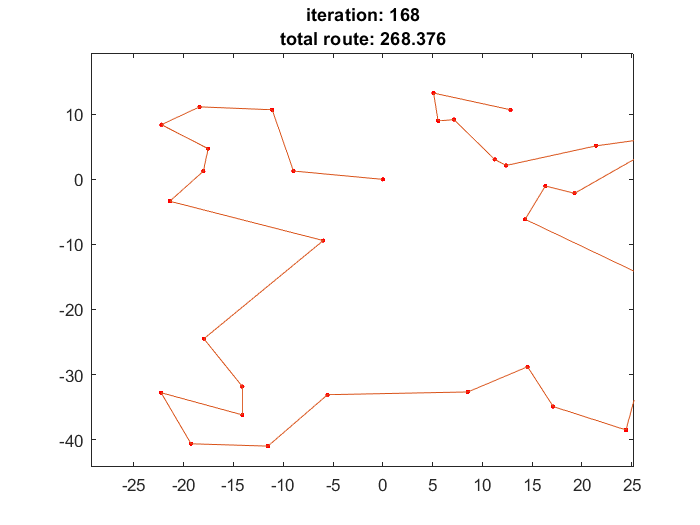

sortedCoords =    12.8270   10.7008
    5.1002   13.2633
    5.5542    8.9770
    7.1443    9.1896
   11.2331    3.0671
   12.3987    2.1387
   21.4132    5.1464
   29.6184    6.8865
   19.2625   -2.1425
   16.3241   -1.0225


sortedCoords_ID =      5
    28
    20
    29
    30
    24
     6
    16
    13
    34



pos = pos_xy;
clf
%prompt = "How many pictures would you like to use? ";
n_pictures = length(pos); %size(rot_opt, 1);
%n_pictures = input(prompt);

[sortedCoords, sortedCoords_ID, ~] = solveTSP([-pos(1:n_pictures, 1:2); [0, 0]], true)


sortedCoords = flip(sortedCoords(1:end-1, :))

sortedCoords =          0    0.0000
   -8.9747    1.2824
  -11.1142   10.6972
  -18.4031   11.1456
  -22.2413    8.4083
  -17.5441    4.7116
  -18.0272    1.2589
  -21.3974   -3.3611
   -5.9816   -9.4053
  -17.9736  -24.4954


sortedCoords_ID = flip(sortedCoords_ID(1:end-1, :))

sortedCoords_ID =      1
    15
     9
    18
    25
    11
    26
    27
     2
    21


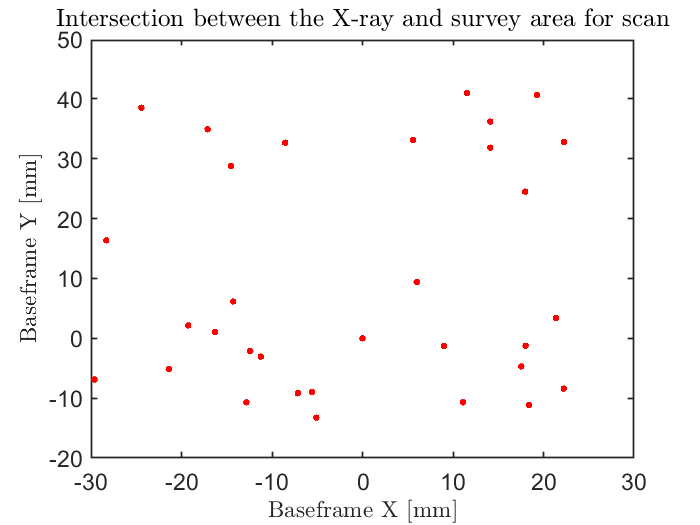


%T = array2table(round([pos_xy_opt(sortedCoords_ID, 5), pos_xy_opt(sortedCoords_ID, 1:2)],3));

%T.Properties.VariableNames(1:3) = {'N','posX','posY'};
%writetable(T,'file1.csv');

clf
figure(4)
plot(pos(1:n_pictures, 1), pos(1:n_pictures, 2), 'r.', 'MarkerSize', 10)
set(0,'DefaultFigureWindowStyle','docked')
set(gca,'FontSize',14)
set(gca,'LineWidth',1)
set(gcf, 'paperunits', 'centimeters', 'Paperposition', [0 0 20 13]);
set(gcf, 'PaperPositionMode', 'auto')
title('Intersection between the X-ray and survey area for scan','interpreter','latex', 'FontSize', 15)
xlabel('Baseframe X $\left[\mathrm{mm}\right]$','interpreter','latex', 'FontSize', 14)
ylabel('Baseframe Y $\left[\mathrm{mm}\right]$','interpreter','latex', 'FontSize', 14)

clf
